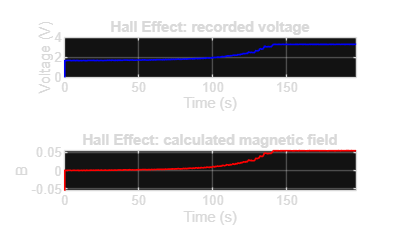

S = load('C:\Users\Admin\Desktop\RMX\Lab\halleffect\halleffect.mat', ...
    'Realtime1');

sigV = getElement(S.Realtime1, 3); % แรงดันจาก Vref
sigB = getElement(S.Realtime1, 2); % ค่า B จาก MATLAB Function

V = sigV.Values;
B = sigB.Values;

figure('Color', 'w');
tiledlayout(2, 1);

nexttile;
plot(V.Time, squeeze(V.Data), 'b', 'LineWidth', 1);
grid on;
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Hall Effect: recorded voltage');
xlim([V.Time(1) V.Time(end)]);

nexttile;
plot(B.Time, squeeze(B.Data), 'r', 'LineWidth', 1);
grid on;
xlabel('Time (s)');
ylabel('B');
title('Hall Effect: calculated magnetic field');
xlim([B.Time(1) B.Time(end)]);